## Solid Liquid Fit Example

First get the problemDefs etc by using an existing RasCAL1 project as usual (use original_DSPC_bilayer from the Rascal demo's folder).

First initialise RAT....

addRatPaths()

debug


Rather than populate the input classes manually, we build them from an existing Rascal project....

[problem,controls] = r1ToProblemDef('original_dspc_bilayer.mat')

problem =   problemDef with properties:

         experimentType: 'standard'
     experimentGeometry: 'substrate/liquid'
                nParams: 22
                 params: [5.0406 18.6723 3.4002e-06 21.0069 -3.4923e-07 5.9060 8.0722 19.8373 4.9879e-10 9.8423 1.0059e-06 6.6955 28.0113 10.0000 1.0000e-06 3.5028 17.1338 -1.6289e-07 16.4869 29.5219 99.9965 23.4506]
             paramNames: {1×22 cell}
            paramConstr: {1×22 cell}
          paramFitYesNo: [1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1]
           nBackgrounds: 2
            backgrounds: [2.0841e-06 3.1708e-06]
        backgroundNames: {'Background D2O'  'Background 2'}
       backgroundConstr: {[5.0000e-10 7.0000e-06]  [1.0000e-10 5.0000e-06]}
     backgroundFitYesNo: [1 1]
          nScalefactors: 2
           scalefactors: [0.1029 0.1432]
       scalefactorNames: {'Scalefactor 1'  'Scalefactor 2'}
      scalefactorConstr: {[0.0500 0.2000]  [0.0500 

controls =   controlsDef with properties:

            parallel: 'single'
           procedure: 'calculate'
    calcSldDuringFit: 'no'


Set up for running simplex...

controls.procedure = 'DE';
controls.maxFunEvals = 1000;
controls.F_weight = 0.3;
controls.numGenerations = 150;
controls.populationSize = 30

controls =   controlsDef with properties:

                parallel: 'single'
               procedure: 'DE'
        calcSldDuringFit: 'no'
          populationSize: 30
                F_weight: 0.3000
    crossoverProbability: 0.8000
                strategy: 4
             targetValue: 1
          numGenerations: 150


Run the fit...

[outProblem,results] = RAT(problem,controls)

***Starting Differential Evolution***
Iteration: 1,  Best: 527.966100,  F_weight: 0.300000,  F_CR: 0.800000,  I_NP: 30
Iteration: 2,  Best: 527.966100,  F_weight: 0.300000,  F_CR: 0.800000,  I_NP: 30
Iteration: 3,  Best: 389.058784,  F_weight: 0.300000,  F_CR: 0.800000,  I_NP: 30
Iteration: 4,  Best: 389.058784,  F_weight: 0.300000,  F_CR: 0.800000,  I_NP: 30
Iteration: 5,  Best: 389.058784,  F_weight: 0.300000,  F_CR: 0.800000,  I_NP: 30
Iteration: 6,  Best: 261.763043,  F_weight: 0.300000,  F_CR: 0.800000,  I_NP: 30
Iteration: 7,  Best: 261.763043,  F_weight: 0.300000,  F_CR: 0.800000,  I_NP: 30
Iteration: 8,  Best: 261.763043,  F_weight: 0.300000,  F_CR: 0.800000,  I_NP: 30
Iteration: 9,  Best: 261.763043,  F_weight: 0.300000,  F_CR: 0.800000,  I_NP: 30
Iteration: 10,  Best: 261.763043,  F_weight: 0.300000,  F_CR: 0.800000,  I_NP: 30
Iteration: 11,  Best: 261.763043,  F_weight: 0.300000,  F_CR: 0.800000,  I_NP: 30
Iteration: 12,  Best: 261.763043,  F_weight: 0.300000,  F_CR: 0.80000

outProblem = struct with fields:
           ssubs: [2×1 double]
     backgrounds: [2×1 double]
         qshifts: [2×1 double]
    scalefactors: [2×1 double]
          nbairs: [2×1 double]
          nbsubs: [2×1 double]
     resolutions: [2×1 double]
    calculations: [1×1 struct]
     allSubRough: [2×1 double]


results = struct with fields:
    reflectivity: {2×1 cell}
      Simulation: {2×1 cell}
    shifted_data: {2×1 cell}
       layerSlds: {2×1 cell}
     sldProfiles: {2×1 cell}
       allLayers: {2×1 cell}


Plot out the results....

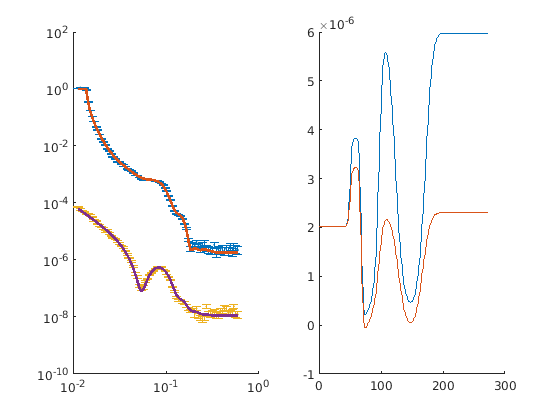

plotRefSLD(outProblem,results)